### ADVANCED MATH MODELLING SAMPLE SCRIPT

#### DEFINING DH

d1 = 0.3; % in cm
t1 = 0; % in deg
l2 = 0.3; %in cm
t2 = pi/3; % in deg
l3 = 0.3; % in cm
t3 = pi/3; % in deg
l4 = 0.3;
d4 = 0.2; % in cm
dh1 = [0 0 d1 t1];
dh2 = [l2 0 0 t2];
dh3 = [l3 0 0 t3];
dh4 = [0 pi d4 0];

#### DEFINING BODIES AND JOINTS

body1 = rigidBody('body1');
jnt1 = rigidBodyJoint('jnt1','revolute');
body2 = rigidBody('body2');
jnt2 = rigidBodyJoint('jnt2','revolute');
body3 = rigidBody('body3');
jnt3 = rigidBodyJoint('jnt3','revolute');
body4 = rigidBody('body4');
jnt4 = rigidBodyJoint('jnt4','prismatic');

#### SETTING FIXED TRANSFORMS

setFixedTransform(jnt1,dh1,"dh");
setFixedTransform(jnt2,dh2,"dh");
setFixedTransform(jnt3,dh3,"dh");
setFixedTransform(jnt4,dh4,"dh");

#### ATTACHING JOINTS TO BODIES

body1.Joint = jnt1;
body2.Joint = jnt2;
body3.Joint = jnt3;
body4.Joint = jnt4;

#### CREATION OF RIGID BODY TREE

robot = rigidBodyTree;
addBody(robot,body1,'base');
addBody(robot,body2,'body1');
addBody(robot,body3,'body2');
addBody(robot,body4,'body3');
showdetails(robot)

--------------------
Robot: (4 bodies)

 Idx    Body Name   Joint Name   Joint Type    Parent Name(Idx)   Children Name(s)
 ---    ---------   ----------   ----------    ----------------   ----------------
   1        body1         jnt1     revolute             base(0)   body2(2)  
   2        body2         jnt2     revolute            body1(1)   body3(3)  
   3        body3         jnt3     revolute            body2(2)   body4(4)  
   4        body4         jnt4    prismatic            body3(3)   
--------------------


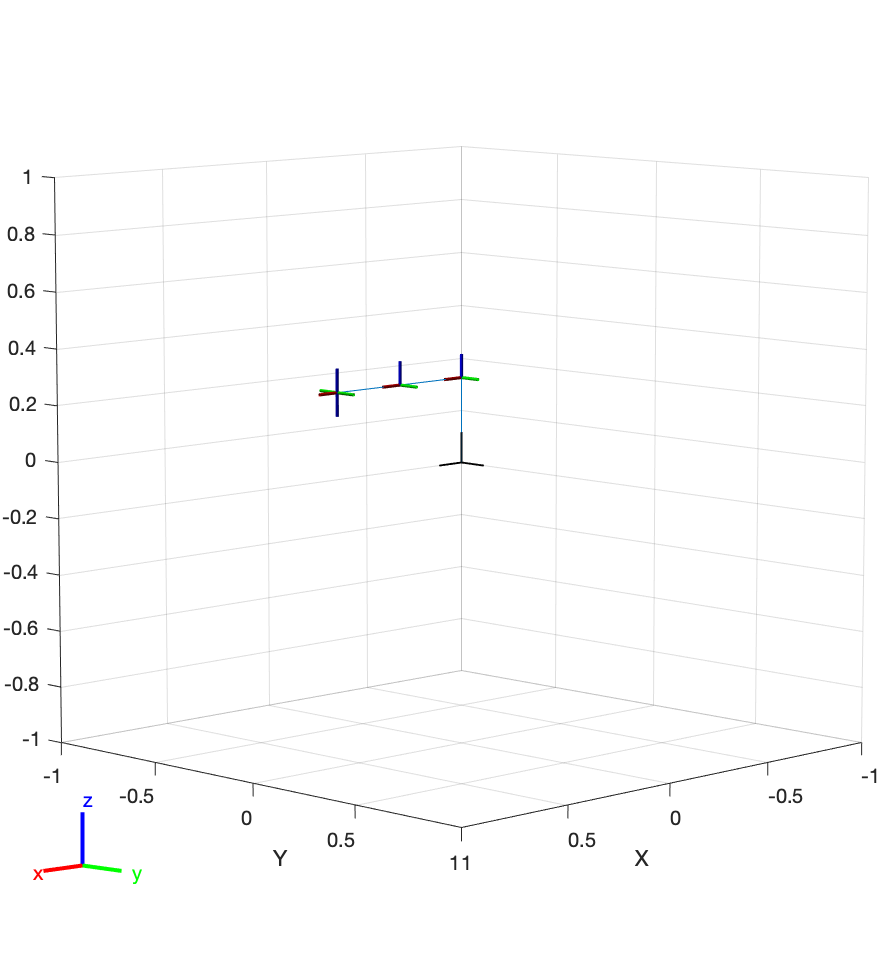

ans =   Axes (Primary) with properties:

             XLim: [-1 1]
             YLim: [-1 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


show(robot)